myData = EEG.data

myData = 30×400×54 single array
myData(:,:,1) =

   -2.0492   -1.7076   -1.3456   -0.9651   -0.5681   -0.1567    0.2671    0.7008    1.1424    1.5894    2.0396    2.4908    2.9406    3.3869    3.8276    4.2606    4.6841    5.0962    5.4952    5.8796    6.2479    6.5989    6.9316    7.2450    7.5383    7.8109    8.0625    8.2926    8.5013    8.6885    8.8545    8.9997    9.1243    9.2290    9.3145    9.3814    9.4306    9.4630    9.4796    9.4814    9.4693    9.4445    9.4078    9.3604    9.3032    9.2372    9.1632    9.0821    8.9946    8.9016    8.8036    8.7013    8.5950    8.4852    8.3722    8.2562    8.1374    8.0159    7.8917    7.7647    7.6350    7.5022    7.3662    7.2268    7.0836    6.9364    6.7850    6.6289    6.4679    6.3017    6.1300    5.9528    5.7698    5.5809    5.3861    5.1853    4.9787    4.7663    4.5484    4.3252    4.0972    3.8646    3.6282    3.3883    3.1456    2.9008    2.6546    2.4078    2.1612    1.9155    1.6717    1.4307    1.1932    0.9600    0.7321 

% square each sample in each epoch
squaredData = myData.^2;

## Dimensions

numEpochs = size(squaredData, 3);
disp("numEpochs: ");

numEpochs: 


disp(numEpochs); 

    54



numSamples = size(squaredData,2);
disp("numSamples (per epoch): ")

numSamples (per epoch): 


disp(numSamples);

   400



numChannels = size(squaredData, 1);  % should be == 1 now, but might apply to more channnels later 
disp("numChannels: ");

numChannels: 


disp(numChannels);

    30



% mean across epochs

% initializing a matrix to store the mean values
epochAvgs = zeros(numEpochs,numChannels);
% option 1: mean of each epoch across all channels
for i = 1:numEpochs
    epochData = squaredData(:,:,i); % stores every sample from epoch[i] (i goes from 1 to 85)
    epochAvgs(i, :) = mean(epochData, 2); % Use '2' to compute the mean along the samples dimension
end
% option 2: mean of each epoch in each channel
% epochAvgs2 = zeros(numEpochs,numChannels);
% for j = 1:numChannels
%     for i = 1:numEpochs
%         epochData = squaredData(j,:,i); % stores every sample from epoch[i] and channel[j] (i goes from 1 to 85, j from 1 to 32)
%         epochAvgs2(i, j) = mean(epochData, 2); % Use '2' to compute the mean along the samples dimension
%     end
% end
disp(' Size of Epoch Averages: ')

 Size of Epoch Averages: 


disp(size(epochAvgs));

    54    30



## Obtaining RT

% find ttlRT only for the event type Probes
probeEvents = strcmp({EEG.event.type}, 'Probe')

probeEvents = 1×108 logical array
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   1   1   0   1   0


numProbes = sum(probeEvents); % Should have 85 'Probe' events (numEpochs)
disp("numProbes: ");

numProbes: 


disp(numProbes);

    54




probeReactionTimes = {EEG.event(probeEvents).ttlRT};
probeReactionTimesMatrix = cell2mat(probeReactionTimes);
disp("probeReactionTimesMatrix: ");

probeReactionTimesMatrix: 


disp(probeReactionTimesMatrix);

    0.3205    0.3825    0.3815    0.3395    0.3400    0.4175    0.3600    0.3540    0.3880    0.3955    0.4425    0.3600    0.5545    0.3545    0.3050    0.4430    0.3535    0.3400    0.5075    0.4430    0.4300    0.3600    0.4840    0.3680    0.6115    0.3545    0.2985    0.3335    0.3885    0.3820    0.4635    0.4435    0.3890    0.4515    0.4365    0.4440    0.3890    0.3670    0.3830    0.4030    0.5825    0.4230    0.4985    0.3960    0.4375    0.4090    0.3050    0.3880    0.3120    0.3755    0.4095    0.3885    0.2430    0.3110



## Fast/Slow Reaction times

% Catergorizing Reaction Times as FAST or SLOW based on median RT value
medianRT = median(probeReactionTimesMatrix);
fprintf("medianRT: %.4f", medianRT);

medianRT: 0.3882


% Categorize as "fast" (1) or "slow" (2)
speedCategories = zeros(1, numProbes); % Initialize vector
speedCategories(probeReactionTimesMatrix >= medianRT) = 2; % "slow" 
speedCategories(probeReactionTimesMatrix < medianRT) = 1  % "fast"

speedCategories =      1     1     1     1     1     2     1     1     1     2     2     1     2     1     1     2     1     1     2     2     2     1     2     1     2     1     1     1     2     1     2     2     2     2     2     2     2     1     1     2     2     2     2     2     2     2     1     1     1     1


disp(speedCategories);

     1     1     1     1     1     2     1     1     1     2     2     1     2     1     1     2     1     1     2     2     2     1     2     1     2     1     1     1     2     1     2     2     2     2     2     2     2     1     1     2     2     2     2     2     2     2     1     1     1     1     2     2     1     1



## Set up an SVM model

% trying SVM (kernel: linear)
% Concatenate squared epoch averages and speed categories
features = [epochAvgs, speedCategories']; % size: 85 x 33 

rng(42); % for reproducibility
numObservations = size(features, 1);
trainRatio = 0.8;
numTrain = round(trainRatio * numObservations);

% Randomly shuffle the data indices (avoid bias)
indices = randperm(numObservations);

% test-train split
trainIndices = indices(1:numTrain);
testIndices = indices(numTrain+1:end);
trainFeatures = features(trainIndices, :);
testFeatures = features(testIndices, :);

Mdl = fitcsvm(trainFeatures(:, 1:end-1), trainFeatures(:, end), 'Standardize', true, 'KernelFunction', 'linear');

% Display information about the trained SVM model
disp(Mdl);

  ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2]
           ScoreTransform: 'none'
          NumObservations: 43
                    Alpha: [31×1 double]
                     Bias: -0.0631
         KernelParameters: [1×1 struct]
                       Mu: [165.6538 128.6439 125.9250 103.4656 99.0915 107.5681 115.2328 100.5355 93.6174 109.1569 105.9374 96.3365 103.9556 100.4649 120.0645 132.8146 324.0069 325.3068 117.5240 99.0423 123.1214 99.8585 117.7483 110.6574 144.4462 … ]
                    Sigma: [181.4751 131.2927 98.6785 92.7024 93.4316 100.7526 116.9827 83.3461 92.5041 100.7461 95.1569 84.4048 102.6149 80.2449 108.9225 172.5362 564.3242 579.9914 81.8348 73.2803 87.4219 75.4702 80.6903 86.6878 113.8821 77.0563 … ]
           BoxConstraints: [43×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [43×1 logical]
                   Solver: 'SM


% Predict on the training data for now (might want to split data into training and testing sets)
predictions = predict(Mdl, testFeatures(:, 1:end-1));

% Display some evaluation metrics
confMat = confusionmat(testFeatures(:, end), predictions);
accuracy = sum(diag(confMat)) / sum(confMat, 'all');
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 27.27%


disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

     0     5
     3     3



% Print out the predicted labels and true labels for debugging
disp('Predicted Labels:');

Predicted Labels:


disp(predictions);

     2
     2
     2
     2
     1
     2
     1
     2
     1
     2
     2



disp('True Labels:');

True Labels:


disp(testFeatures(:, end));

     2
     2
     1
     1
     2
     1
     2
     1
     2
     2
     1



## including k- fold cv

% Define the number of folds (k)
k = 5; 
% Set up k-fold cross-validation
cv = cvpartition(size(features, 1), 'KFold', k);

rng(42);

% Initialize variables to store performance metrics
accuracyList = zeros(k, 1);
confMatList = cell(k, 1);

% Perform k-fold cross-validation
for i = 1:k
    % Split the data into training and validation sets for this fold
    trainIndices = training(cv, i);
    testIndices = test(cv, i);
    trainData = features(trainIndices, :);
    testData = features(testIndices, :);
    
    % Train the SVM model on the training set
    Mdl = fitcsvm(trainData(:, 1:end-1), trainData(:, end), 'Standardize', true, 'KernelFunction', 'linear');
    
    % Predict on the validation set
    predictions = predict(Mdl, testData(:, 1:end-1));
    
    % Evaluate model performance
    confMat = confusionmat(testData(:, end), predictions);
    accuracy = sum(diag(confMat)) / sum(confMat, 'all');
    
    % Store performance metrics for this fold
    accuracyList(i) = accuracy;
    confMatList{i} = confMat;
    
    % Display performance for this fold (optional)
    fprintf('Fold %d - Accuracy: %.2f%%\n', i, accuracy * 100);
end

Fold 1 - Accuracy: 30.00%
Fold 2 - Accuracy: 54.55%
Fold 3 - Accuracy: 27.27%
Fold 4 - Accuracy: 54.55%
Fold 5 - Accuracy: 81.82%



% Compute average accuracy across all folds
avgAccuracy = mean(accuracyList);

fprintf('Average Accuracy: %.2f%%\n', avgAccuracy * 100);

Average Accuracy: 49.64%


## Extracting features

% % Extract support vectors and indices
% supportVectors = Mdl.SupportVectors;
% supportVectorIndices = Mdl.IsSupportVector;  
% disp(supportVectors); % Each row of supportVectors corresponds to one support vector
% 
% % Extract coefficients and bias
% coefficients = Mdl.Beta;
% bias = Mdl.Bias;
% disp(coefficients);
% 
% % Extract other model properties
% %kernelFunction = Mdl.KernelFunction;
% %kernelScale = Mdl.KernelScale;
% %boxConstraint = Mdl.BoxConstraint;

## Plot the data and decision boundary

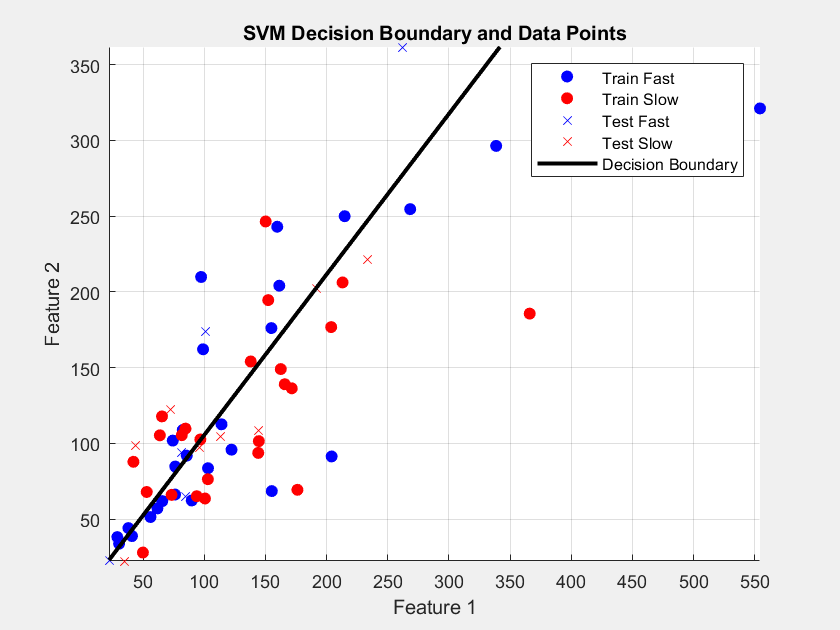

set(0, 'DefaultFigureCreateFcn', @(~,~) set(gcf,'Visible','on'));
set(0, 'DefaultFigureRenderer', 'opengl');
set(0, 'DefaultFigureVisible', 'on');

% Plot Data Points
figure;
hold on;
% Plot Fast instances
scatter(trainData(trainData(:, end) == 1, 1), trainData(trainData(:, end) == 1, 2), 'bo', 'filled');
scatter(trainData(trainData(:, end) == 2, 1), trainData(trainData(:, end) == 2, 2), 'ro', 'filled');
% Plot Slow instances
scatter(testData(testData(:, end) == 1, 1), testData(testData(:, end) == 1, 2), 'bx');
scatter(testData(testData(:, end) == 2, 1), testData(testData(:, end) == 2, 2), 'rx');

% Plot Decision Boundary
w = Mdl.Beta; % Coefficients of the hyperplane
b = Mdl.Bias; % Intercept of the hyperplane
x1 = linspace(min(trainFeatures(:, 1)), max(trainFeatures(:, 1)), 100);
x2 = (-w(1)*x1 - b) / w(2); % Compute decision boundary
plot(x1, x2, 'k-', 'LineWidth', 2);

% Add labels and legend
xlabel('Feature 1');
ylabel('Feature 2');
legend('Train Fast', 'Train Slow', 'Test Fast', 'Test Slow', 'Decision Boundary');
title('SVM Decision Boundary and Data Points');

% Set axis limits
xlim([min(trainFeatures(:, 1)) max(trainFeatures(:, 1))]);
ylim([min(trainFeatures(:, 2)) max(trainFeatures(:, 2))]);

% Show grid
grid on;

## Laplacian

% % Example Laplacian weights for 32 channels (adjust according to your electrode configuration)
% weights = [1/4, 1, 1, 4, 1/4, 1, 1, 1, 1/4, 1, 1, 1, 1, 1, 1/4, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1]; % Define the weights for each electrode's neighbors
% % ^ first quadrant sorted out
% 
% % Initialize array to store Laplacian-transformed data
% laplacianData = zeros(size(myData)); 
% 
% % Apply Laplacian transform
% numChannels = size(myData, 1);
% for i = 1:numChannels
%     neighbors = find(neighborsMatrix(i, :)); % Find neighboring electrodes
%     numNeighbors = numel(neighbors);
% 
%     % Calculate weighted average signal
%     weightedSum = sum(myData(neighbors, :), 1); % Sum signals of neighboring electrodes
%     weightedAverage = weightedSum * weights(neighbors)' / sum(weights(neighbors)); % Weighted average
% 
%     % Subtract weighted average from original signal
%     laplacianData(i, :) = myData(i, :) - weightedAverage;
% end


## Preprocessing: ALPHA phase for each epoch

% do I use myData OR squared data below?

Fs = EEG.srate; % Sampling frequency (Hz)
f1 = 8; % Lower frequency of the bandpass filter (Hz)
f2 = 12; % Upper frequency of the bandpass filter (Hz)

% Bandpass filter the EEG data
[b, a] = butter(2, [f1, f2]/(Fs/2), 'bandpass'); % Design bandpass filter

probeAlphaPhase = zeros(numChannels,numEpochs);
alphaPhase = zeros(numChannels,numEpochs,numSamples);
alphaHilbert = zeros(numChannels,numEpochs,numSamples);
alphaBandpass = zeros(numChannels,numEpochs,numSamples);
alphaPower = zeros(numChannels,numEpochs,numSamples);
probeAlphaPower = zeros(numChannels,numEpochs);

for i = 1:numEpochs
    alphaBandpass(:,i,:) = filtfilt(b, a, myData(:,:,i)); % Apply bandpass filter for Epoch 'i'

    alphaHilbert(:,i,:) = hilbert(alphaBandpass(:,i,:)); % Compute envelope using Hilbert transform
    alphaPhase(:,i,:) = angle(alphaHilbert(:,i,:));
    alphaPower(:,i,:) = abs(alphaHilbert(:,i,:));
    % Extract phase
    probeAlphaPhase(:,i) = alphaPhase(:,i,200); % Phase at index 2000 of Hilbert transform
    % Extract amplitude
    probeAlphaPower(:, i) = alphaPower(:,i, 200); % Amplitude at index 2000 of Hilbert transform

end

## Preprocessing: THETA phase for each epoch

% do I use myData OR squared data below?

Fs = EEG.srate; % Sampling frequency (Hz)
f3 = 4; % Lower frequency of the bandpass filter (Hz)
f4 = 8; % Upper frequency of the bandpass filter (Hz)

% Bandpass filter the EEG data
[d, c] = butter(2, [f3, f4]/(Fs/2), 'bandpass'); % Design bandpass filter

probeThetaPhase = zeros(numChannels,numEpochs);
thetaPhase = zeros(numChannels,numEpochs,numSamples);
thetaHilbert = zeros(numChannels,numEpochs,numSamples);
thetaBandpass = zeros(numChannels,numEpochs,numSamples);
thetaPower = zeros(numChannels,numEpochs,numSamples);
probeThetaPower = zeros(numChannels,numEpochs);

for i = 1:numEpochs
    thetaBandpass(:,i,:) = filtfilt(d, c, myData(:,:,i)); % Apply bandpass filter for Epoch 'i'

    % Hilbert transform
    thetaHilbert(:,i,:) = hilbert(thetaBandpass(:,i,:)); % Compute envelope using Hilbert transform
    thetaPhase(:,i,:) = angle(thetaHilbert(:,i,:));
    thetaPower(:,i,:) = abs(thetaHilbert(:,i,:));
    % Extract phase
    probeThetaPhase(:,i) = thetaPhase(:,i,200); % Phase at index 2000 of Hilbert transform

    % Extract amplitude
    probeThetaPower(:, i) = thetaPower(:,i, 200); % Amplitude at index 2000 of Hilbert transform

end

## Phase visualization

% Plotting
% figure;
% t = (0:size(myData, 2)-1) / Fs; % Time vector (s)
% 
% plot(t, alphaPhase(1,85,:), t, alphaBandpass(1,85,:), 'm');
% title('Phase of Hilbert Transform');
% xlabel('Time (s)');
% ylabel('Phase');

## Average AlphaPhases

avgAlpha = mean(probeAlphaPhase,1);
avgAlpha = avgAlpha';

## Average ThetaPhases

avgTheta = mean(probeThetaPhase, 1);
avgTheta = avgTheta';

## try popeegfilt

% EEG = pop_loadset('your_eeg_data.set');
% 
% thetaLowFreq = 4;
% thetaHighFreq = 8;
% 
% % Apply bandpass filter for theta band using pop_eegfilt
% EEG_theta = pop_eegfilt(myData, thetaLowFreq, thetaHighFreq, [], 0, [], 0, 'fir1', 0);
% 
% % Extract theta phase and power
% thetaPh = zeros(numChannels, numEpochs, numSamples);
% thetaPow = zeros(numChannels, numEpochs, numSamples);
% 
% for epoch = 1:numEpochs
%     for channel = 1:numChannels
%         % Extract data for current channel and epoch
%         epochData = EEG_theta.data(channel, :, epoch);
% 
%         % Compute Hilbert transform to get the analytic signal
%         hilbertTransform = hilbert(epochData);
% 
%         % Extract phase and power from the analytic signal
%         thetaPhase(channel, epoch, :) = angle(hilbertTransform);
%         thetaPower(channel, epoch, :) = abs(hilbertTransform).^2;
%     end
% end


## Exclude speed values in the middle quartile #1 : failed

% % Sort probeReactionTimesMatrix in ascending order
% sortedReactionTimes = sort(probeReactionTimesMatrix);
% 
% % Calculate quartiles
% Q1 = prctile(sortedReactionTimes, 38);  
% Q3 = prctile(sortedReactionTimes, 62);  
% 
% % Exclude values falling within the middle quartile
% excludedIndices = sortedReactionTimes >= Q1 & sortedReactionTimes <= Q3;
% filteredReactionTimes = sortedReactionTimes(~excludedIndices);
% 
% % Find the original indices of excluded values in the unsorted matrix
% excludedOriginalIndices = find(excludedIndices);
% 
% % NEW fast/slow speed categories
% % Categorize as "fast" (1) or "slow" (2)
% filtSpeedCategories = zeros(size(filteredReactionTimes)); % Initialize vector
% filtSpeedCategories(filteredReactionTimes >= medianRT) = 2; % "slow" 
% filtSpeedCategories(filteredReactionTimes < medianRT) = 1  % "fast"

filtSpeedCategories =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


% disp(filtSpeedCategories);

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2



## Exclude speed values in the middle quartile #2

% Sort reaction times while preserving original indices
[sortedReactionTimes, sortedIndices] = sort(probeReactionTimesMatrix);

% Calculate quartiles
Q1 = prctile(sortedReactionTimes, 40);
Q3 = prctile(sortedReactionTimes, 60);

% Identify indices of epochs corresponding to middle quartile
middleQuartileIndices = sortedIndices(sortedReactionTimes >= Q1 & sortedReactionTimes <= Q3);

% Exclude epochs from EEG data and speed categories
filteredEEGData = EEG.data(:, :, ~ismember(1:numEpochs, middleQuartileIndices));
filteredSpeedCategories = speedCategories(~ismember(1:numEpochs, middleQuartileIndices));

## Selected Indices of Features


% Exclude epochs from other features
filteredThetaPhase = probeThetaPhase(~ismember(1:numEpochs, middleQuartileIndices));
filteredAlphaPhase = probeAlphaPhase(~ismember(1:numEpochs, middleQuartileIndices));

filteredThetaPower = probeThetaPower(~ismember(1:numEpochs, middleQuartileIndices));
filteredAlphaPower = probeAlphaPower(~ismember(1:numEpochs, middleQuartileIndices));

## Add Phase to features

% concatenate EEG phase with other features
features = [probeAlphaPhase', probeAlphaPower', probeThetaPhase', probeThetaPower', speedCategories']; % Concatenate epoch averages, phase, and speed categories

## SVM with Phase Features

% Define the number of folds (k)
k = 5; 
% Set up k-fold cross-validation
cv = cvpartition(size(features, 1), 'KFold', k);

rng(42);

% Initialize variables to store performance metrics
accuracyList = zeros(k, 1);
confMatList = cell(k, 1);

% Perform k-fold cross-validation
for i = 1:k
    % Split the data into training and validation sets for this fold
    trainIndices = training(cv, i);
    testIndices = test(cv, i);
    trainData = features(trainIndices, :);
    testData = features(testIndices, :);
    
    % Train the SVM model on the training set
    Mdl = fitcsvm(trainData(:, 1:end-1), trainData(:, end), 'Standardize', true, 'KernelFunction',  'linear');
    
    % Predict on the validation set
    predictions = predict(Mdl, testData(:, 1:end-1));
    
    % Evaluate model performance
    confMat = confusionmat(testData(:, end), predictions);
    accuracy = sum(diag(confMat)) / sum(confMat, 'all');
    
    % Store performance metrics for this fold
    accuracyList(i) = accuracy;
    confMatList{i} = confMat;
    
    % Display performance for this fold (optional)
    fprintf('Fold %d - Accuracy: %.2f%%\n', i, accuracy * 100);
end

Fold 1 - Accuracy: 70.00%
Fold 2 - Accuracy: 72.73%
Fold 3 - Accuracy: 63.64%
Fold 4 - Accuracy: 45.45%
Fold 5 - Accuracy: 54.55%



% Compute average accuracy across all folds
avgAccuracy = mean(accuracyList);

fprintf('Average Accuracy: %.2f%%\n', avgAccuracy * 100);

Average Accuracy: 61.27%


## Add Phase to filtered features (filtered Speed Cats)

% concatenate EEG phase with other features
features_filt = [filteredAlphaPhase', filteredAlphaPower', filteredThetaPhase', filteredThetaPower', filteredSpeedCategories']; % Concatenate epoch averages, phase, and speed categories
% adding probeThetaPhase' as a feature decrease the predict by 3%

## SVM with Phase Features & Filtered Speed Categories

% Define the number of folds (k)
k = 5; 
% Set up k-fold cross-validation
cv = cvpartition(size(features_filt, 1), 'KFold', k);

rng(42);

% Initialize variables to store performance metrics
accuracyList = zeros(k, 1);
confMatList = cell(k, 1);

% Perform k-fold cross-validation
for i = 1:k
    % Split the data into training and validation sets for this fold
    trainIndices = training(cv, i);
    testIndices = test(cv, i);
    trainData = features_filt(trainIndices, :);
    testData = features_filt(testIndices, :);
    
    % Train the SVM model on the training set
    Mdl = fitcsvm(trainData(:, 1:end-1), trainData(:, end), 'Standardize', true, 'KernelFunction',  'linear');
    
    % Predict on the validation set
    predictions = predict(Mdl, testData(:, 1:end-1));
    
    % Evaluate model performance
    confMat = confusionmat(testData(:, end), predictions);
    accuracy = sum(diag(confMat)) / sum(confMat, 'all');
    
    % Store performance metrics for this fold
    accuracyList(i) = accuracy;
    confMatList{i} = confMat;
    
    % Display performance for this fold (optional)
    fprintf('Fold %d - Accuracy: %.2f%%\n', i, accuracy * 100);
end

Fold 1 - Accuracy: 62.50%
Fold 2 - Accuracy: 66.67%
Fold 3 - Accuracy: 55.56%
Fold 4 - Accuracy: 55.56%
Fold 5 - Accuracy: 55.56%



% Compute average accuracy across all folds
avgAccuracy = mean(accuracyList);

fprintf('Average Accuracy: %.2f%%\n', avgAccuracy * 100);

Average Accuracy: 59.17%


## Selected Channels

% Indices of the channels to select
% selectedIndices = [1, 5, 6, 9, 11, 12, 16, 17, 22, 23, 24, 28, 31, 32]; % added [5,9,11,23,24,31] because of filtfilt
% selChannelsData = myData(selectedIndices,:,:);
% numChannels2 = size(selChannelsData,1);

## ALPHA & THETA with selected channels(different approach)

% % ALPHA
% 
% Fs = EEG.srate; % Sampling frequency (Hz)
% f1 = 8; % Lower frequency of the bandpass filter (Hz)
% f2 = 12; % Upper frequency of the bandpass filter (Hz)
% 
% % Bandpass filter the EEG data
% [b, a] = butter(2, [f1, f2]/(Fs/2), 'bandpass'); % Design bandpass filter
% 
% probeAlphaPhase2 = zeros(numChannels2,numEpochs);
% alphaPhase2 = zeros(numChannels2,numEpochs,numSamples);
% alphaHilbert2 = zeros(numChannels2,numEpochs,numSamples);
% alphaBandpass2 = zeros(numChannels2,numEpochs,numSamples);
% alphaPower2 = zeros(numChannels2,numEpochs,numSamples);
% probeAlphaPower2 = zeros(numChannels2,numEpochs);
% 
% for i = 1:numEpochs
%     alphaBandpass2(:,i,:) = filtfilt(b, a, selChannelsData(:,:,i)); % Apply bandpass filter for Epoch 'i'
% 
%     alphaHilbert2(:,i,:) = hilbert(alphaBandpass2(:,i,:)); % Compute envelope using Hilbert transform
%     alphaPhase2(:,i,:) = angle(alphaHilbert2(:,i,:));
%     alphaPower2(:,i,:) = abs(alphaHilbert2(:,i,:));
%     % Extract phase
%     probeAlphaPhase2(:,i) = alphaPhase2(:,i,2000); % Phase at index 2000 of Hilbert transform
%     % Extract amplitude
%     probeAlphaPower2(:,i) = alphaPower2(:,i,200);
% end
% 
% % THETA
% 
% f3 = 4; % Lower frequency of the bandpass filter (Hz)
% f4 = 8; % Upper frequency of the bandpass filter (Hz)
% 
% % Bandpass filter the EEG data
% [d, c] = butter(2, [f3, f4]/(Fs/2), 'bandpass'); % Design bandpass filter
% 
% probeThetaPhase2 = zeros(numChannels2,numEpochs);
% thetaPhase2 = zeros(numChannels2,numEpochs,numSamples);
% thetaHilbert2 = zeros(numChannels2,numEpochs,numSamples);
% thetaBandpass2 = zeros(numChannels2,numEpochs,numSamples);
% thetaPower2 = zeros(numChannels2,numEpochs,numSamples);
% probeThetaPower2 = zeros(numChannels2,numEpochs);
% 
% for i = 1:numEpochs
%     thetaBandpass2(:,i,:) = filtfilt(d, c, selChannelsData(:,:,i)); % Apply bandpass filter for Epoch 'i'
% 
%     % Hilbert transform
%     thetaHilbert2(:,i,:) = hilbert(thetaBandpass2(:,i,:)); % Compute envelope using Hilbert transform
%     thetaPhase2(:,i,:) = angle(thetaHilbert2(:,i,:));
%     thetaPower2(:,i,:) = abs(thetaHilbert2(:,i,:));
%     % Extract phase
%     probeThetaPhase2(:,i) = thetaPhase2(:,i,2000); % Phase at index 2000 of Hilbert transform
%     % Extract amplitude
%     probeThetaPower2(:,i) = thetaPower2(:,i,2000); % Power at index 2000 of Hilbert transform
% end
% 
% % Average AlphaPhase
% avgAlpha2 = mean(probeAlphaPhase2, 1);
% avgAlpha2 = avgAlpha2';
% % Average ThetaPhase
% avgTheta2 = mean(probeThetaPhase2, 1);
% avgTheta2 = avgTheta2';


## SVM with selected channels

% features2 = [avgTheta2, avgAlpha2, probeThetaPower2', probeAlphaPower2', speedCategories'];
% % Define the number of folds (k)
% k = 5; 
% % Set up k-fold cross-validation
% cv = cvpartition(size(features2, 1), 'KFold', k);
% 
% rng(42);
% 
% % Initialize variables to store performance metrics
% accuracyList = zeros(k, 1);
% confMatList = cell(k, 1);
% 
% % Perform k-fold cross-validation
% for i = 1:k
%     % Split the data into training and validation sets for this fold
%     trainIndices = training(cv, i);
%     testIndices = test(cv, i);
%     trainData = features2(trainIndices, :);
%     testData = features2(testIndices, :);
% 
%     % Train the SVM model on the training set
%     Mdl2 = fitcsvm(trainData(:, 1:end-1), trainData(:, end), 'Standardize', true, 'KernelFunction',  'linear');
% 
%     % Predict on the validation set
%     predictions = predict(Mdl2, testData(:, 1:end-1));
% 
%     % Evaluate model performance
%     confMat = confusionmat(testData(:, end), predictions);
%     accuracy = sum(diag(confMat)) / sum(confMat, 'all');
% 
%     % Store performance metrics for this fold
%     accuracyList(i) = accuracy;
%     confMatList{i} = confMat;
% 
%     % Display performance for this fold (optional)
%     fprintf('Fold %d - Accuracy: %.2f%%\n', i, accuracy * 100);
% end

Fold 1 - Accuracy: 47.06%
Fold 2 - Accuracy: 58.82%
Fold 3 - Accuracy: 29.41%
Fold 4 - Accuracy: 64.71%
Fold 5 - Accuracy: 41.18%


% 
% % Compute average accuracy across all folds
% avgAccuracy = mean(accuracyList);
% 
% fprintf('Average Accuracy: %.2f%%\n', avgAccuracy * 100);

Average Accuracy: 48.24%
